# PatchCore_Train

#### **Fred liu 2023.07.17**

**update 2024.02.17**

2023a之後的版本更新了三種異常偵測的演算法，分別是：

**Fully convolitional data description(FCDD)**

**FastFlow**

**PatchCore**

詳細資訊可以在此連結中找到：[Getting Started with Anomaly Detection Using Deep Learning](https://www.mathworks.com/help/vision/ug/getting-started-with-anomaly-detection-using-deep-learning.html)

### Download DataSet VisA

使用Dataset :  [VisA Visual Inspection Dataset](https://github.com/amazon-science/spot-diff)

Only load normal sample

Normaldatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal";
Anomalydatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Anomaly";

### 載入資料與資料分割(Load Data & Splits Dataset )

NormaldsPCB = imageDatastore(Normaldatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(NormaldsPCB.Labels)

     Normal      1005 


AnomalydsPCB = imageDatastore(Anomalydatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(AnomalydsPCB.Labels)

     Anomaly      100 


分割少量資料做訓練

%[dsTrain,dsVal,dsTest] = splitAnomalyData(dsPCB,"Anomaly");
[NormaldsPCB_10,NormaldsPCB_90] = splitEachLabel(NormaldsPCB,0.1)

NormaldsPCB_10 =   ImageDatastore with properties:

                       Files: {
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0000.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0001.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0002.JPG'
                               ... and 98 more
                              }
                     Folders: {
                              ' ...\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal'
                              }
                      Labels: [Normal; Normal; Normal ... and 98 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

NormaldsPCB_90 =   ImageDatastore with properties:

                       Files: {
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0101.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0102.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0103.JPG'
                               ... and 901 more
                              }
                     Folders: {
                              ' ...\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal'
                              }
                      Labels: [Normal; Normal; Normal ... and 901 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                  

### 顯示資料庫影像

正常影像

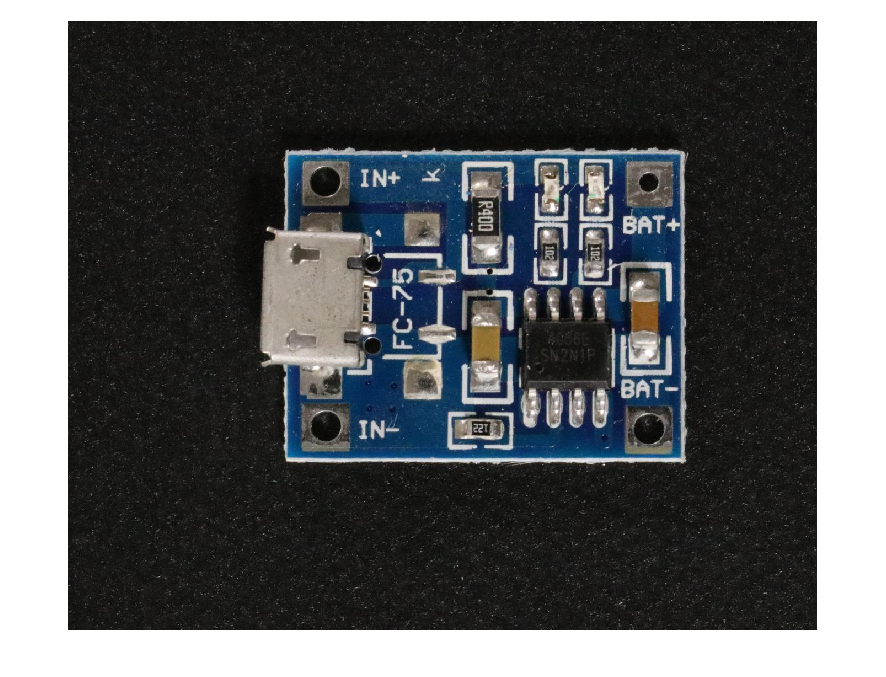

figure,imshow(preview(NormaldsPCB))

異常影像

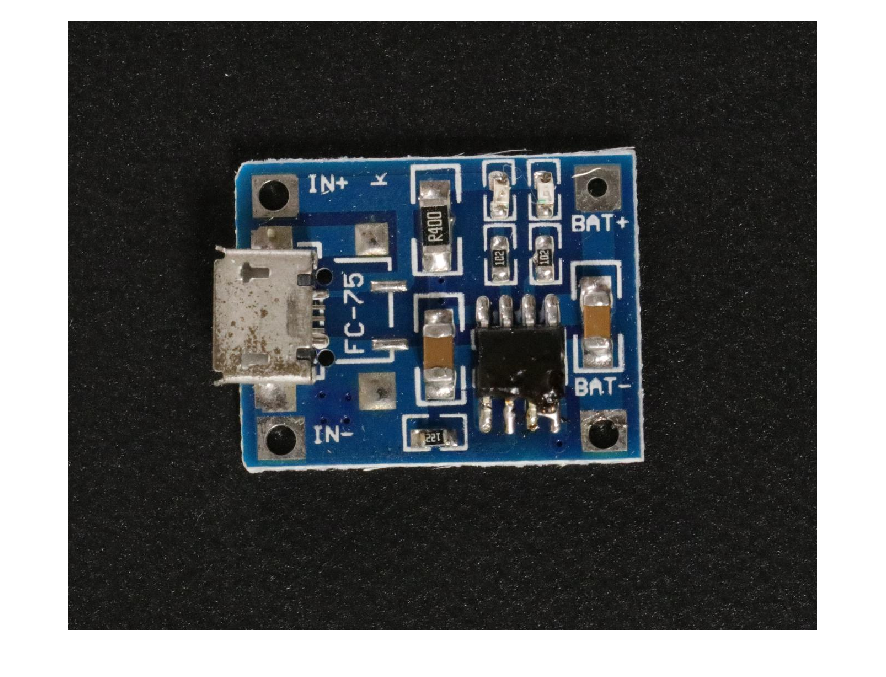

figure,imshow(preview(AnomalydsPCB))

### 資料前處理(resize and preview)

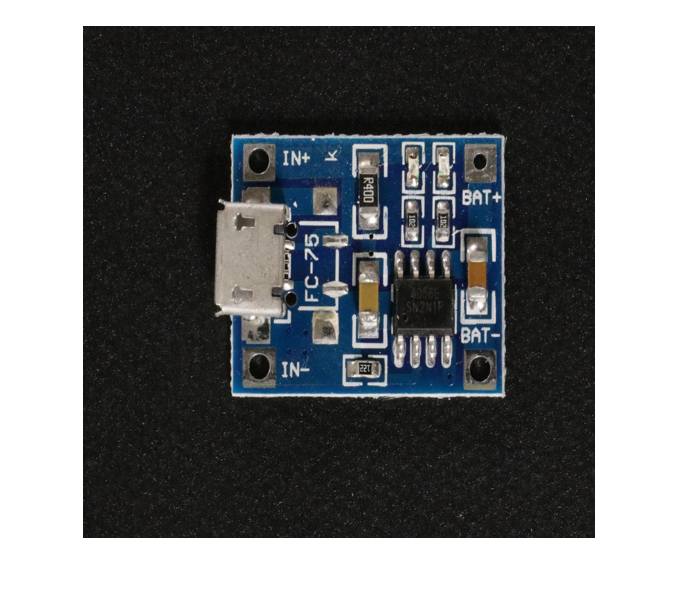

resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
NormaldsPCB_10 = transform(NormaldsPCB_10,resizeFcn);
figure,imshow(preview(NormaldsPCB_10))

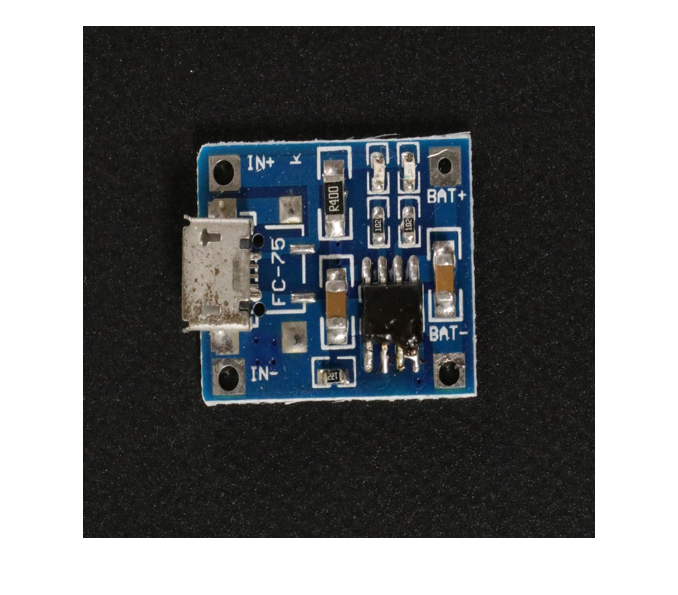

resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
AnomalydsPCB = transform(AnomalydsPCB,resizeFcn);
figure,imshow(preview(AnomalydsPCB))

### 建立模型(PatchCore)

resnet18 & restnet50可以做選擇

patchCore = patchCoreAnomalyDetector(Backbone = "resnet50")

patchCore =   patchCoreAnomalyDetector with properties:

    Threshold: []
    ImageSize: []


### 切割驗證資料集

%dsValGoodIdx = dsVal.UnderlyingDatastores{1}.Labels == "Normal";
%dsValGood = subset(dsVal,dsValGoodIdx);
%dsValBad = subset(dsVal,~dsValGoodIdx);

### 訓練與參數設定

detector_patch = trainPatchCoreAnomalyDetector(NormaldsPCB_10,patchCore,CompressionRatio=0.1)

Computing Input Normalization Statistics.
Training PatchCore Model.
-------------------------

Step 1: Computing embeddings for each minibatch
.Done creating uncompressed train embeddings.
Step 2: Compress train embeddings at 0.1 factor to create a coreset...

Computing coreset samples

Completed 4137 of 41369  Time: Calculating...

Completed 8274 of 41369  Time: 00:23 of 01:56

Completed 12411 of 41369  Time: 00:35 of 01:56

Completed 16548 of 41369  Time: 00:46 of 01:56

Completed 20685 of 41369  Time: 00:58 of 01:56

Completed 24822 of 41369  Time: 01:09 of 01:56

Completed 28959 of 41369  Time: 01:21 of 01:56

Completed 33096 of 41369  Time: 01:33 of 01:56

Completed 37233 of 41369  Time: 01:44 of 01:56
Done compressing train embeddings (coreset).
Done training PatchCore model.


detector =   patchCoreAnomalyDetector with properties:

    Threshold: []
    ImageSize: [512 512 3]


### 測試影像

載入單張影像進行異常偵測測試

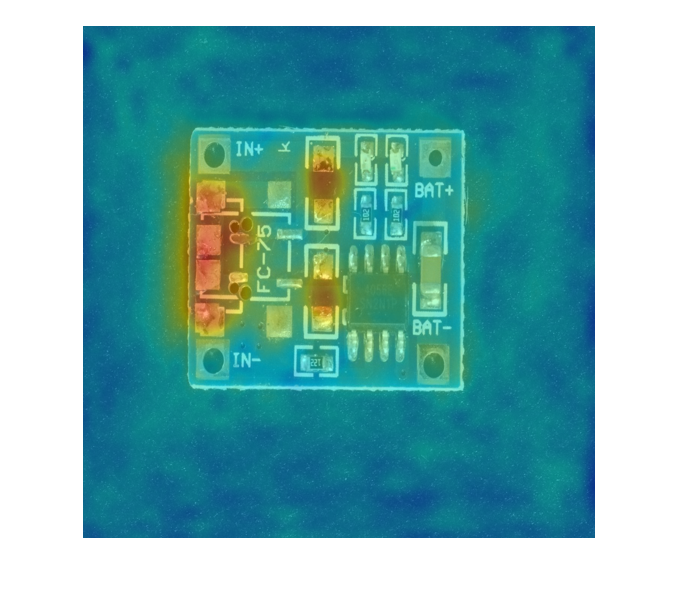

AnomalyImage = imread("D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Anomaly\065.JPG");
%AnomalyImage = imread("D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0012.JPG");
AnomalyImage = imresize(AnomalyImage,[512 512]);
displayRange = [0,30];
map2 = anomalyMap(detector_patch,AnomalyImage);
image2 = (anomalyMapOverlay(AnomalyImage,map2,MapRange=displayRange,Blend="equal"));
%image2 = (anomalyMapOverlay(AnomalyImage,map2,Blend="equal"));
figure,imshow(image2)

## 資料庫檢測

Testdatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\";
TestdsPCB = imageDatastore(Testdatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(TestdsPCB.Labels)

     Anomaly       100 
     Normal       1005 


resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
TestdsPCB = transform(TestdsPCB,resizeFcn);
figure,imshow(preview(TestdsPCB))

gtLabels = TestdsPCB.UnderlyingDatastores{1,1}.Labels;
anomalyLabels = "Anomaly";
predScores = predict(detector_patch,TestdsPCB);

View the anomaly detection results.

[T,roc] = anomalyThreshold(gtLabels,predScores,anomalyLabels)

T = single
16.7536

roc =   rocmetrics with properties:

    Metrics: [1106×4 table]
        AUC: 0.9930


  Properties, Methods


viewAnomalyDetectionResults(detector_patch,TestdsPCB,gtLabels,predScores,anomalyLabels);

Error using vision.internal.ui.inspection.AnomalyDetectionBrowser/validateDetector
Threshold property must be set to a valid anomaly threshold prior to calling classify.

Error in vision.internal.ui.inspection.AnomalyDetectionBrowser (line 70)
            validateDetector(self,detector);

Error in <a hre